close all; clear all; clc

## Lab 7

*Name: Joshua Yap*

*Lab Partner: Dane Thorn*

In this lab, we aim to optimize event selection.

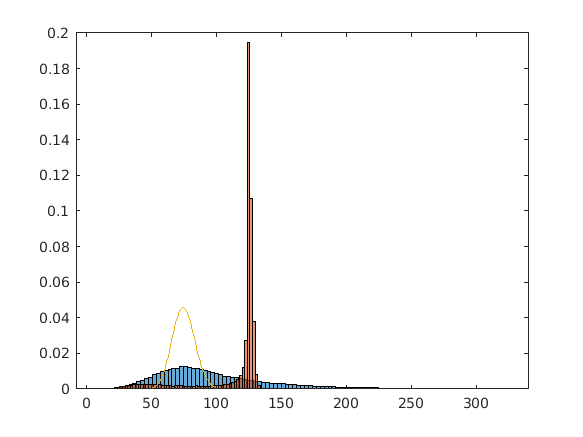

dataQCD = h5read('qcd_100000_pt_250_500.h5','/qcd_100000_pt_250_500')';
dataHiggs = h5read("higgs_100000_pt_250_500.h5","/higgs_100000_pt_250_500")';

massQCD = dataQCD(:,4);
massHiggs = dataHiggs(:,4);
histogram(massQCD,'Normalization','pdf')
hold on
histogram(massHiggs,'Normalization','pdf')
fit1 = poissfit(massQCD);
x = 0:300;
plot(x,pdf('Poisson',x,75))
hold off

The maximum on the QCD background is approximately 75, and the spike of the Higgs data is at approximately 125. We will use these values as the averages of each data set to calculate the significance of the Higgs signal.

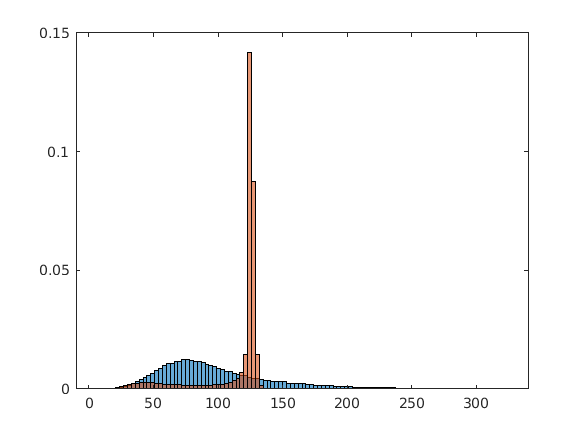

prob1 = poisscdf(125,75,'upper');
sig1 = norminv(1-prob1);
% Normalize data sets
nMassQCD = (massQCD./sum(massQCD)).*20000;
nMassHiggs = (massHiggs./sum(massHiggs)).*100;
figure
h1 = histogram(massQCD,'Normalization','pdf');
hold on
h2 = histogram(massHiggs,'Normalization','pdf');
h2.BinWidth = h1.BinWidth;
hold off

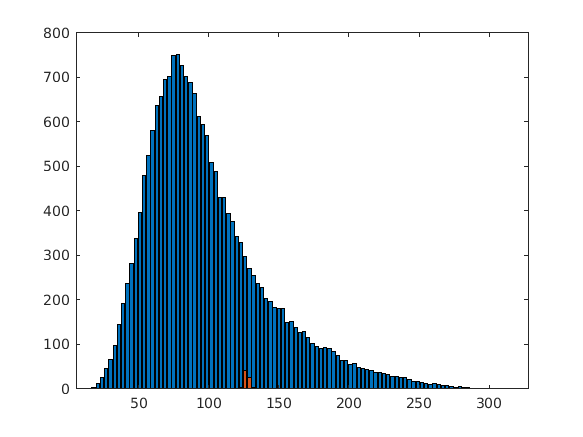

% figure
% h1 = histogram(massQCD)
% hold on
% h2 = histogram(massHiggs)
% hold off
sum(h2.Values);
figure
% QCD
b1 = bar(h1.BinEdges(2:end),(h1.Values./sum(h1.Values))*20000);
hold on
% Higgs
b2 = bar(h2.BinEdges(2:end),(h2.Values./sum(h2.Values))*100);

b1width = b1.XData(2)-b1.XData(1);
b2width = b2.XData(2)-b2.XData(1);
b1area = sum(b1.YData);
b2area = sum(b2.YData);

The bar chart above shows the histogram of QCD counts and Higgs counts once we scale them to their respective expected yields. It is easy to see that the area of the Higgs spike is far outweighed by the area of the QCD background since there are many more background events than signal events. The tail on the background to the right of the spike is much larger than the normalized histogram, and using this to compute the significance of the signal yields a much smaller value.

% Compute fractional area of upper tail
p1 = sum(b1.YData(39:end))./b1area;
sig1 = norminv(1-p1);
disp(['Expected significance = ',num2str(sig1),' sigma'])

Expected significance = 0.75345 sigma


We want to compare this with $\frac{N_{\textrm{Higgs}} }{\sqrt{\;N_{\textrm{QCD}} }}$ and see if they are equivalent, for $N_{\textrm{Higgs}} =100$ and $N_{\textrm{QCD}} =20000$.

ratio1 = 100/sqrt(20000);
disp(['Ratio = ',num2str(ratio1)])

Ratio = 0.70711


These are approximately equal, so in subsequent steps we can use the ratio to calculate the significance of the signal, as opposed to finding the area of the upper tail and then converting that to a sigma value.

This next section aims to identify mass cuts we can make to get the highest significance of the signal. The central idea is to keep as much of the signal counts as possible while throwing out as much of the QCD counts as we can, in order to maximize the ratio $\frac{N_{\textrm{Higgs}} }{\sqrt{\;N_{\textrm{QCD}} }}$. We will try many different values of mass to cut the data at and see which one gives us the highest significance.

% start values range from 50 to 140
qcdStart = 14:44;
higgsStart = 15:length(b2.XData)-1;
% end values range from 54 to 144
qcdFinish = 15:45;
higgsFinish = 16:length(b2.XData);

ratio2 = zeros(length(qcdStart),length(qcdFinish));
for ii = 1:length(qcdStart)
    for jj = 1:length(qcdFinish)
        % Sum areas of QCD and Higgs histogram in range
        % use ratio to compute significance
        qcdCounts = sum(b1.YData(qcdStart(ii):qcdFinish(jj)));
        higgsCounts = sum(b2.YData(higgsStart(ii):higgsFinish(jj)));
        ratio2(ii,jj) = higgsCounts/sqrt(qcdCounts);
    end
end
% Check that loop computes correct thing
% qcdCheck = sum(b1.YData);
% higgsCheck = sum(b2.YData);
% ratioCheck = higgsCheck./sqrt(qcdCheck)
[optSig,optCut] = max(ratio2(:));
[optStart,optEnd] = find(ratio2 == optSig);
t2 = array2table(ratio2(21:30,21:30));
rownames = arrayfun(@num2str,b1.XData(33:42),'uni',0);
colnames = arrayfun(@num2str,b1.XData(35:44),'uni',0);
t2.Properties.RowNames = rownames;
t2.Properties.VariableNames = colnames;
disp(t2)

             114         117         120        123       126       129        132        135         138          141   
           ________    ________    _______    _______    ______    ______    _______    _______    _________    _________

    108    0.064196     0.09132    0.13375    0.22361    1.1199    1.5871     1.5936     1.5373       1.4819       1.4363
    111    0.052105     0.08486    0.13325    0.23349    1.2313    1.7306     1.7213     1.6481        1.579       1.5231
    114         NaN    0.068086     0.1272    0.24191    1.3717    1.9041     1.8697     1.7728       1.6855       1.616

The table above shows the significance for a range of mass cuts. The index of each row represents the start of the cut and the index of each column corresponds to the end of the cut.

Interestingly, although unsurprisingly, the mass cut that gives us the highest significance is very narrow. The mass cut 123 < mass < 129 yields a significance of 2.8827$\sigma$, the highest of any cut. 

Set A of plots - without event selection

The following plots are the rest of the data features. We plot them to see if there are any other features as discriminative as mass.

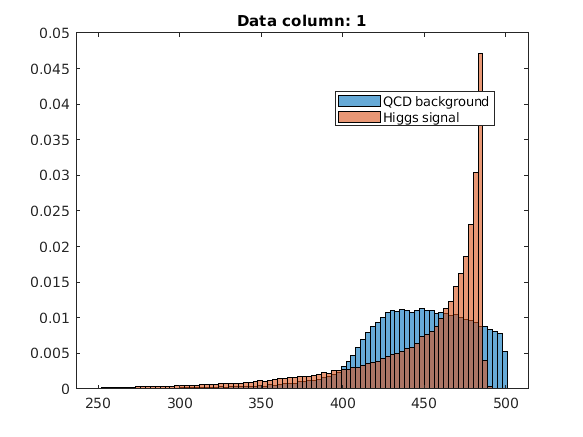

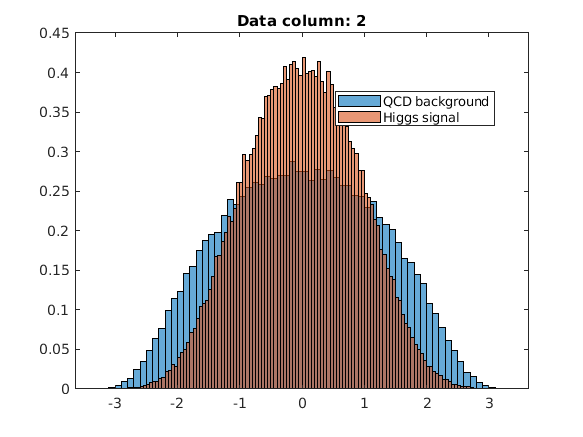

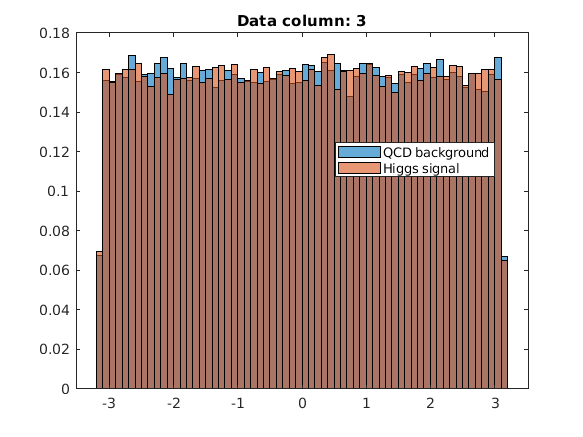

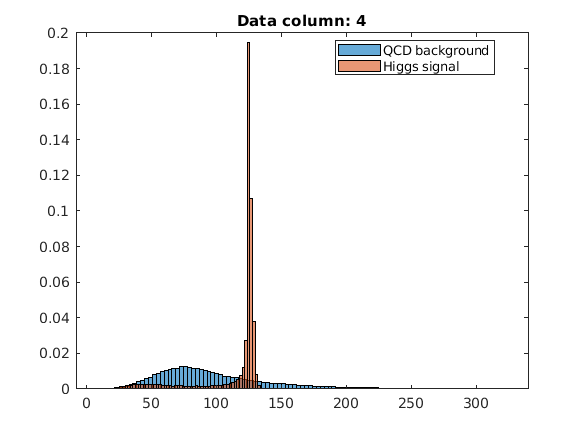

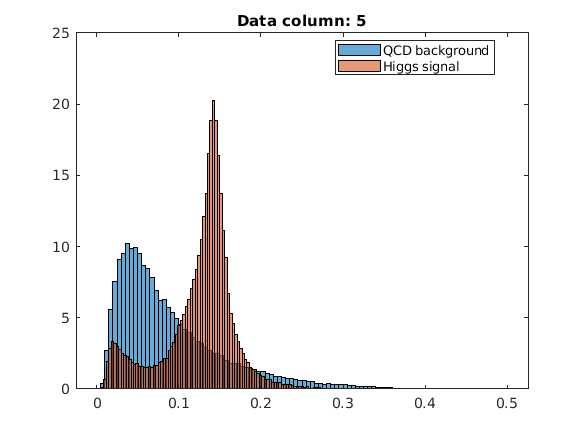

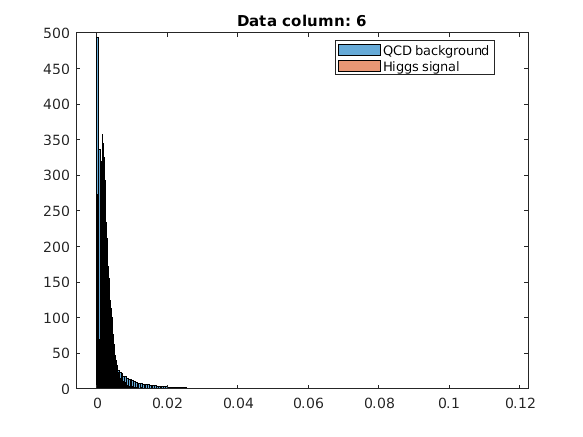

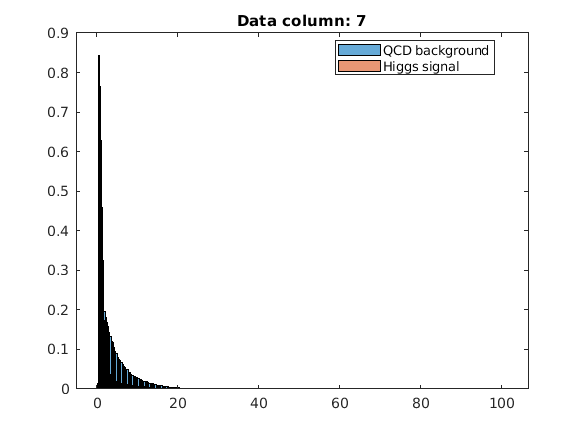

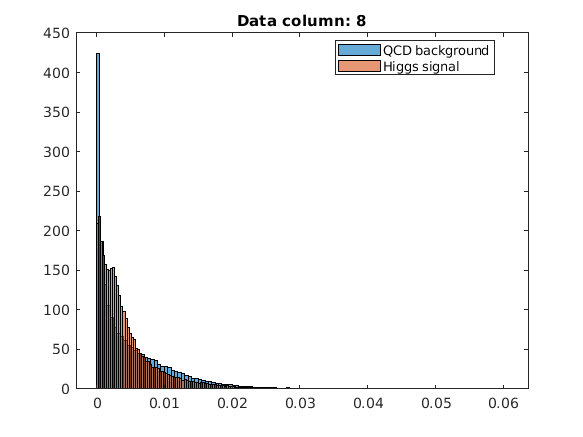

for jj=1:14
    figure
    histogram(dataQCD(:,jj),'Normalization','pdf')
    hold on
    histogram(dataHiggs(:,jj),'Normalization','pdf')
    hold off
    title(['Data column: ',num2str(jj)])
    legend('QCD background','Higgs signal','Location','best')
end

In order to be better at discriminating background from signal, we are looking for histograms where there is the least overlap between background and signal data. Data column 4 is the mass data that we previously analyzed, so that is our benchmark to choose other discriminating features. Just from eyeballing the plots, it looks like only columns 10,11 and 12 are worth looking at. The other data columns exhibit too much overlap between the two data sets. These variables correspond to $\tau_2$, $\tau_3$ and $\tau_{21}$ (2-subjettiness, 3-subjettiness and ratio of 2-subjettiness to 1-subjettiness respectively). We perform the same analysis on these columns as we did above for mass in order to determine if they are better discriminating variables.

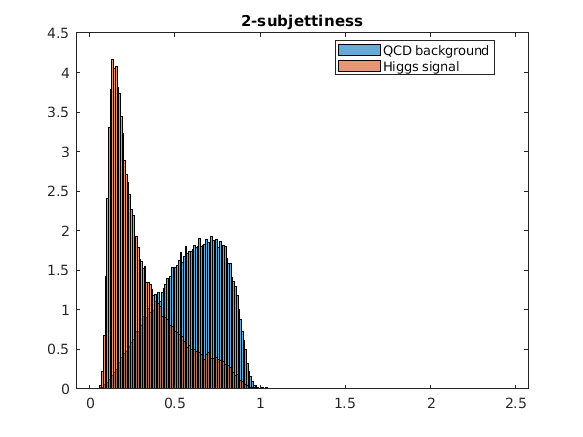

t2QCD = dataQCD(:,10);
t2Higgs = dataHiggs(:,10);
figure
h3QCD = histogram(t2QCD,'Normalization','pdf');
hold on
h3Higgs = histogram(t2Higgs,'Normalization','pdf');
h3QCD.BinWidth = h3Higgs.BinWidth;
hold off
title('2-subjettiness')
legend('QCD background','Higgs signal','Location','best')

The plot above is normalized such that the area under each histogram is 1. Once we rescale the histograms to the expected yields, we obtain the plot below.

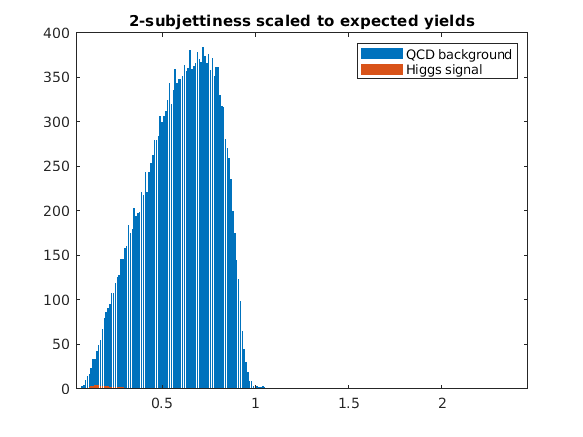

figure
% QCD
b3QCD = bar(h3QCD.BinEdges(2:end),(h3QCD.Values./sum(h3QCD.Values)).*20000);
hold on
% Higgs
b3Higgs = bar(h3Higgs.BinEdges(2:end),(h3Higgs.Values./sum(h3Higgs.Values)).*100);
title('2-subjettiness scaled to expected yields')
legend('QCD background','Higgs signal')
hold off

b3QCDwidth = b3QCD.XData(2)-b3QCD.XData(1);
b3Higgswidth = b3Higgs.XData(2)-b3Higgs.XData(1);
b3QCDarea = sum(b3QCD.YData);
b3Higgsarea = sum(b3Higgs.YData);

The Higgs signal is barely visible once rescaled to expected yields. Similar to the analysis of mass data, we treat the peak of the Higgs signal as the signal value. This time we compute the probability of the lower tail of QCD background, since the signal is towards the lower end of the distribution and a lower value therefore indicates a more signal-like observation.

% Compute fractional area of lower tail
[maxV,index] = max(b3Higgs.YData);
xVal = b3Higgs.XData(index);
xIndex = find(b3QCD.XData==xVal);
p3a = sum(b3QCD.YData(1:xIndex))./b3QCDarea;
sig3a = abs(norminv(p3a));
disp(['Expected significance = ',num2str(sig3a),' sigma'])

Expected significance = 2.4512 sigma


Without making any cuts, the significance is 2.4512$\sigma$, already higher than for the mass data. This seems artificially high because we approximated the Higgs signal value as the peak, but the distribution is much more uniform than for the mass data, so we may have to use the average of the Higgs data as the signal value.

% Take weighted average
avg = (b3Higgs.YData*b3Higgs.XData')/sum(b3Higgs.YData);
xIndex = find(b3QCD.XData>avg);
p3a = sum(b3QCD.YData(1:xIndex(1)))/b3QCDarea;
sig3a = abs(norminv(p3a));
disp(['Expected significance = ',num2str(sig3a),' sigma'])

Expected significance = 1.2561 sigma


Using the average of signal values weighted by the number of counts, we obtain a significance of 1.2561$\sigma$, much lower than when we approximate the signal value by the peak. We will use this sigma value in our subsequent calculations.

Next we want to identify cuts to make to maximize $\frac{N_{\textrm{Higgs}} }{\sqrt{\;N_{\textrm{QCD}} }}$. We will do it in a manner similar to what we did above to determine mass cuts.

% start values range from 0.06 to 0.50
qcdStart = 2:46;
higgsStart = 1:45;
% end values range from 0.07 to 0.51
qcdFinish = 3:47;
higgsFinish = 2:46;

ratio3 = zeros(length(qcdStart),length(qcdFinish));
for ii = 1:length(qcdStart)
    for jj = 1:length(qcdFinish)
        % Sum areas of QCD and Higgs histogram in range
        % use ratio to compute significance
        qcdCounts = sum(b3QCD.YData(qcdStart(ii):qcdFinish(jj)));
        higgsCounts = sum(b3Higgs.YData(higgsStart(ii):higgsFinish(jj)));
        ratio3(ii,jj) = higgsCounts./sqrt(qcdCounts);
    end
end

% Display table
[optSig,optCut] = max(ratio3(:));
[optStart,optEnd] = find(ratio3 == optSig);
t3 = array2table(ratio3(1:10,11:20));
rownames = arrayfun(@num2str,b3QCD.XData(2:11),'uni',0);
colnames = arrayfun(@num2str,b3QCD.XData(13:22),'uni',0);
t3.Properties.RowNames = rownames;
t3.Properties.VariableNames = colnames;
disp(t3)

             0.17       0.18      0.19      0.2       0.21      0.22      0.23      0.24      0.25      0.26 
            _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    0.06     1.6426    1.6777    1.6817    1.6773    1.6652    1.6513    1.6302     1.613    1.5887     1.565
    0.07     1.6451    1.6798    1.6834    1.6787    1.6664    1.6523     1.631    1.6137    1.5893    1.5655
    0.08     1.6529    1.6861    1.6883    1.6826    1.6695    1.6549    1.6331    1.6155    1.5908    1.5666
    0.09     1.6523    1.6846    1.6861  

Once again, row indices correspond to the starting value of $\tau_2$ while columns correspond to the end value. The maximum significance we obtain is 1.6883$\sigma$ for a cut from 0.08 to 0.19.

We next perform the analysis for $\tau_3$. Since the same method is used, only the results will be discussed.

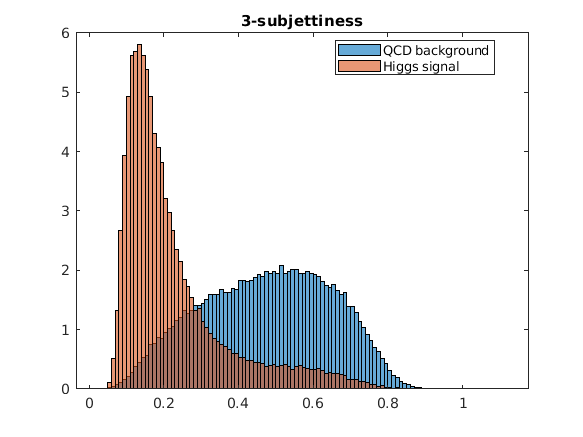

t3QCD = dataQCD(:,11);
t3Higgs = dataHiggs(:,11);
figure
h3QCD = histogram(t3QCD,'Normalization','pdf');
hold on
h3Higgs = histogram(t3Higgs,'Normalization','pdf');
h3QCD.BinWidth = h3Higgs.BinWidth;
hold off
title('3-subjettiness')
legend('QCD background','Higgs signal','Location','best')

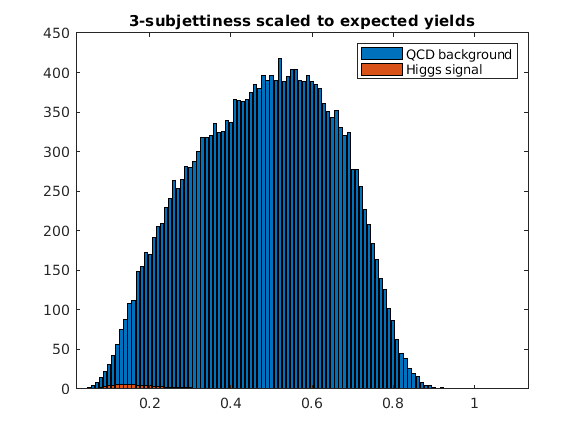

figure
% QCD
b3QCD = bar(h3QCD.BinEdges(2:end),(h3QCD.Values./sum(h3QCD.Values)).*20000);
hold on
% Higgs
b3Higgs = bar(h3Higgs.BinEdges(2:end),(h3Higgs.Values./sum(h3Higgs.Values)).*100);
title('3-subjettiness scaled to expected yields')
legend('QCD background','Higgs signal')
hold off

b3QCDwidth = b3QCD.XData(2)-b3QCD.XData(1);
b3Higgswidth = b3Higgs.XData(2)-b3Higgs.XData(1);
b3QCDarea = sum(b3QCD.YData);
b3Higgsarea = sum(b3Higgs.YData);

% Compute fractional area of lower tail using weighted average
avg = (b3Higgs.YData*b3Higgs.XData')/sum(b3Higgs.YData);
xIndex = find(b3QCD.XData>avg);
p3a = sum(b3QCD.YData(1:xIndex(1)))/b3QCDarea;
sig3a = abs(norminv(p3a));
disp(['Expected significance = ',num2str(sig3a),' sigma'])

Expected significance = 1.2688 sigma


% start values range from 0.04 to 0.40
qcdStart = 2:38;
higgsStart = 1:37;
% end values range from 0.05 to 0.41
qcdFinish = 3:39;
higgsFinish = 2:38;

ratio3 = zeros(length(qcdStart),length(qcdFinish));
for ii = 1:length(qcdStart)
    for jj = 1:length(qcdFinish)
        % Sum areas of QCD and Higgs histogram in range
        % use ratio to compute significance
        qcdCounts = sum(b3QCD.YData(qcdStart(ii):qcdFinish(jj)));
        higgsCounts = sum(b3Higgs.YData(higgsStart(ii):higgsFinish(jj)));
        ratio3(ii,jj) = higgsCounts./sqrt(qcdCounts);
    end
end

% Display table
[optSig,optCut] = max(ratio3(:));
[optStart,optEnd] = find(ratio3 == optSig);
t3 = array2table(ratio3(1:10,11:20));
rownames = arrayfun(@num2str,b3QCD.XData(2:11),'uni',0);
colnames = arrayfun(@num2str,b3QCD.XData(13:22),'uni',0);
t3.Properties.RowNames = rownames;
t3.Properties.VariableNames = colnames;
disp(t3)

             0.15      0.16      0.17      0.18      0.19      0.2       0.21      0.22      0.23      0.24 
            ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    0.04    1.7051    1.7529    1.7442    1.7275    1.7037    1.6896    1.6559    1.6206    1.5871    1.5474
    0.05    1.7054    1.7531    1.7444    1.7276    1.7038    1.6897     1.656    1.6207    1.5872    1.5474
    0.06    1.7077     1.755    1.7458    1.7287    1.7046    1.6904    1.6565    1.6211    1.5875    1.5477
    0.07     1.711    1.7573    1.7471    1.72

A cut from 0.07 to 0.16 yields the highest significance of 1.7573$\sigma$.

Next we look at $\tau_{21}$. Again we only discuss the results.

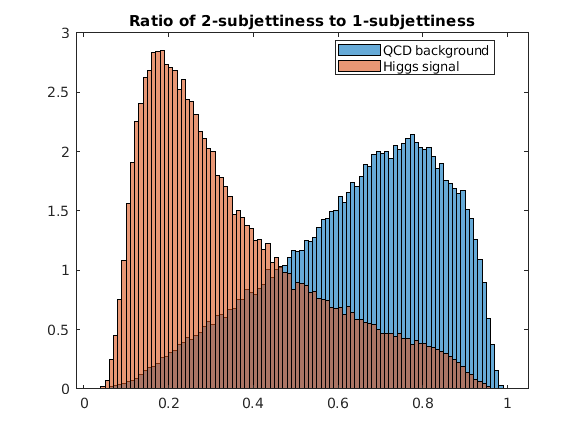

t21QCD = dataQCD(:,12);
t21Higgs = dataHiggs(:,12);
figure
h3QCD = histogram(t21QCD,'Normalization','pdf');
hold on
h3Higgs = histogram(t21Higgs,'Normalization','pdf');
h3Higgs.BinWidth = h3QCD.BinWidth;
hold off
title('Ratio of 2-subjettiness to 1-subjettiness')
legend('QCD background','Higgs signal','Location','best')

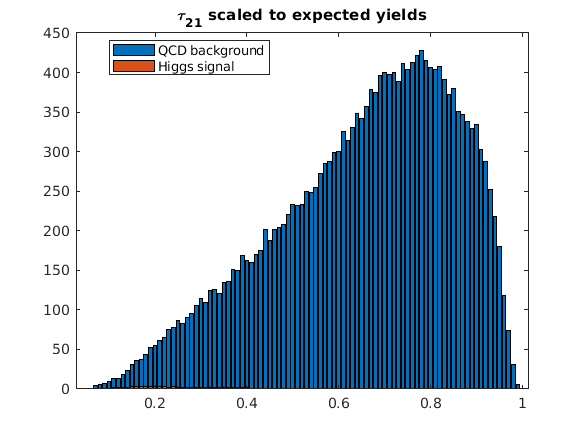

figure
% QCD
b3QCD = bar(h3QCD.BinEdges(2:end),(h3QCD.Values./sum(h3QCD.Values)).*20000);
hold on
% Higgs
b3Higgs = bar(h3Higgs.BinEdges(2:end),(h3Higgs.Values./sum(h3Higgs.Values)).*100);
title('{\tau_{21}} scaled to expected yields','Interpreter','tex')
legend('QCD background','Higgs signal','Location','best')
hold off

b3QCDwidth = b3QCD.XData(2)-b3QCD.XData(1);
b3Higgswidth = b3Higgs.XData(2)-b3Higgs.XData(1);
b3QCDarea = sum(b3QCD.YData);
b3Higgsarea = sum(b3Higgs.YData);

% Compute fractional area of lower tail using weighted average
avg = (b3Higgs.YData*b3Higgs.XData')/sum(b3Higgs.YData);
xIndex = find(b3QCD.XData>avg);
p3a = sum(b3QCD.YData(1:xIndex(1)))/b3QCDarea;
sig3a = abs(norminv(p3a));
disp(['Expected significance = ',num2str(sig3a),' sigma'])

Expected significance = 1.2934 sigma


% start values range from 0.04 to 0.50
qcdStart = 1:47;
higgsStart = 1:47;
% end values range from 0.05 to 0.51
qcdFinish = 2:48;
higgsFinish = 2:48;

ratio3 = zeros(length(qcdStart),length(qcdFinish));
for ii = 1:length(qcdStart)
    for jj = 1:length(qcdFinish)
        % Sum areas of QCD and Higgs histogram in range
        % use ratio to compute significance
        qcdCounts = sum(b3QCD.YData(qcdStart(ii):qcdFinish(jj)));
        higgsCounts = sum(b3Higgs.YData(higgsStart(ii):higgsFinish(jj)));
        ratio3(ii,jj) = higgsCounts./sqrt(qcdCounts);
    end
end

% Display table
[optSig,optCut] = max(ratio3(:));
[optStart,optEnd] = find(ratio3 == optSig);
t3 = array2table(ratio3(1:10,16:25));
rownames = arrayfun(@num2str,b3QCD.XData(1:10),'uni',0);
colnames = arrayfun(@num2str,b3QCD.XData(17:26),'uni',0);
t3.Properties.RowNames = rownames;
t3.Properties.VariableNames = colnames;
disp(t3)

             0.2       0.21      0.22      0.23      0.24      0.25      0.26      0.27      0.28      0.29 
            ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    0.04    1.4555    1.4762    1.4954    1.4973    1.5057    1.5025    1.5079    1.5066    1.5008    1.4902
    0.05    1.4559    1.4765    1.4957    1.4975    1.5059    1.5027     1.508    1.5067    1.5009    1.4904
    0.06    1.4568    1.4772    1.4963    1.4979    1.5062    1.5029    1.5082    1.5069     1.501    1.4904
    0.07    1.4549    1.4753    1.4944    1.49

A cut from 0.06 to 0.26 yields the highest significance of 1.5082$\sigma$.

Summary

**Variable                    Significance                    Significance after cut                    Cut Range**

Mass                          0.7535                              2.8827                                             123 - 129

$\tau_2$                               1.2561                              1.6883                                             0.08 - 0.19

$\tau_3$                               1.2688                              1.7573                                             0.07 - 0.16

$\tau_{21}$                              1.2934                              1.5082                                             0.06 - 0.26

As seen from the table, none of the other variables come close to matching the significance of mass data after making the cut. We next explore event selection using a combination of features, in particular one highlighted in Lab 5: $e_2 /e_3$. This corresponds to dividing column 5 by column 6. We will do the same analysis as above and see if significance improves.

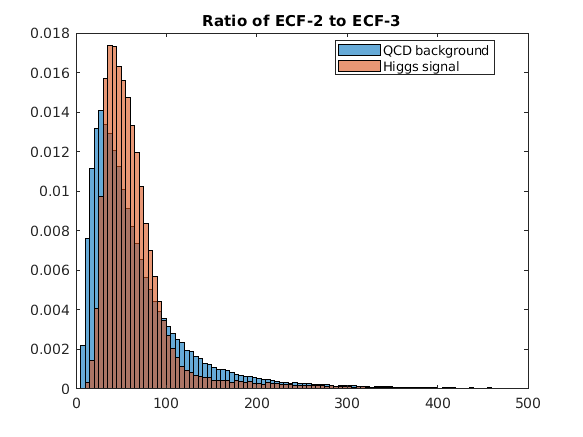

e23QCD = dataQCD(:,5)./dataQCD(:,6);
e23Higgs = dataHiggs(:,5)./dataHiggs(:,6);
figure
h3QCD = histogram(e23QCD,'Normalization','pdf');
hold on
h3Higgs = histogram(e23Higgs,'Normalization','pdf');
h3Higgs.BinWidth = h3QCD.BinWidth;
hold off
title('Ratio of ECF-2 to ECF-3')
legend('QCD background','Higgs signal','Location','best')
xlim([0 500])

Taking one look at this histogram, we can tell that it will not yield a better significance because the histograms overlap too much and there is no cut we can make that will meaningfully increase significance. One other thing we can do is try what we did in Lab 5 and use $1/d_2$ as the discriminating variable (equal to ${\left(e_2 \right)}^3 /e_3$, which corresponds to inverting values in column 7.

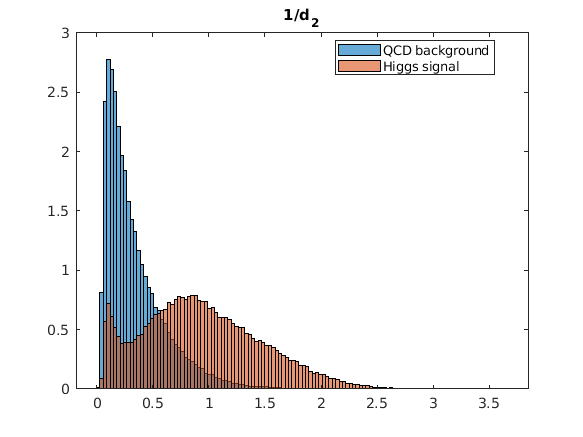

d2invQCD = 1./dataQCD(:,7);
d2invHiggs = 1./dataHiggs(:,7);
figure
h3QCD = histogram(d2invQCD,'Normalization','pdf');
hold on
h3Higgs = histogram(d2invHiggs,'Normalization','pdf');
h3QCD.BinWidth = h3Higgs.BinWidth;
hold off
title('1/d_{2}')
legend('QCD background','Higgs signal','Location','best')

This plot looks like it has a chance to give us a higher significance, so we continue with the analysis.

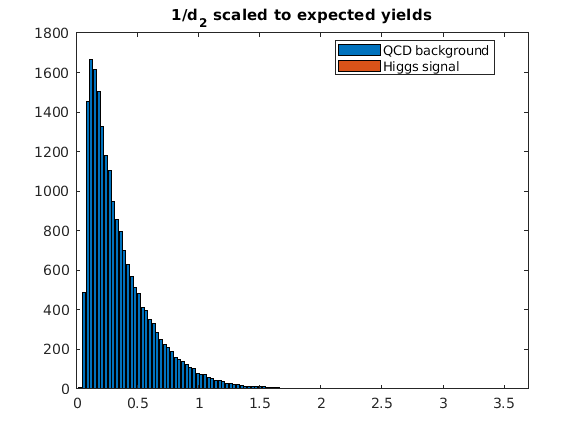

figure
% QCD
b3QCD = bar(h3QCD.BinEdges(2:end),(h3QCD.Values./sum(h3QCD.Values)).*20000);
hold on
% Higgs
b3Higgs = bar(h3Higgs.BinEdges(2:end),(h3Higgs.Values./sum(h3Higgs.Values)).*100);
title('1/d_{2} scaled to expected yields')
legend('QCD background','Higgs signal','Location','best')
hold off

b3QCDwidth = b3QCD.XData(2)-b3QCD.XData(1);
b3Higgswidth = b3Higgs.XData(2)-b3Higgs.XData(1);
b3QCDarea = sum(b3QCD.YData);
b3Higgsarea = sum(b3Higgs.YData);

% Compute fractional area of upper tail using weighted average
avg = (b3Higgs.YData*b3Higgs.XData')/sum(b3Higgs.YData);
xIndex = find(b3QCD.XData>avg);
p3a = sum(b3QCD.YData(xIndex(1):end))/b3QCDarea;
sig3a = abs(norminv(p3a));
disp(['Expected significance = ',num2str(sig3a),' sigma'])

Expected significance = 1.7308 sigma


% start values range from 0.03 to 3.45 in steps of 0.03
qcdStart = 1:115;
higgsStart = 1:115;
% end values range from 0.06 to 3.48 in steps of 0.03
qcdFinish = 2:116;
higgsFinish = 2:116;

ratio3 = zeros(length(qcdStart),length(qcdFinish));
for ii = 1:length(qcdStart)
    for jj = 1:length(qcdFinish)
        % Sum areas of QCD and Higgs histogram in range
        % use ratio to compute significance
        qcdCounts = sum(b3QCD.YData(qcdStart(ii):qcdFinish(jj)));
        higgsCounts = sum(b3Higgs.YData(higgsStart(ii):higgsFinish(jj)));
        ratio3(ii,jj) = higgsCounts./sqrt(qcdCounts);
    end
end

% Ignore Inf values
ratio3 = ratio3.*isfinite(ratio3);
% Display table
[optSig,optCut] = max(ratio3(:));
[optStart,optEnd] = find(ratio3 == optSig);
t3 = array2table(ratio3(36:45,86:95));
rownames = arrayfun(@num2str,b3QCD.XData(36:45),'uni',0);
colnames = arrayfun(@num2str,b3QCD.XData(87:96),'uni',0);
t3.Properties.RowNames = rownames;
t3.Properties.VariableNames = colnames;
disp(t3)

             2.61      2.64      2.67      2.7       2.73      2.76      2.79      2.82      2.85      2.88 
            ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    1.08    1.6965    1.6973    1.6977    1.6985    1.6992    1.6997    1.7004    1.7004    1.7006    1.7002
    1.11    1.7088    1.7096    1.7101    1.7108    1.7116    1.7121    1.7129    1.7128     1.713    1.7125
    1.14    1.7241     1.725    1.7254    1.7262    1.7271    1.7276    1.7284    1.7283    1.7285    1.7279
    1.17    1.7338    1.7347    1.7352    1.73

With a cut from 1.23 to 2.79, we obtain the maximum significance of 1.7616$\sigma$. We can update the summary table.

Summary

**Variable                    Significance                    Significance after cut                    Cut Range**

Mass                          0.7535                              2.8827                                             123 - 129

$\tau_2$                               1.2561                              1.6883                                             0.08 - 0.19

$\tau_3$                               1.2688                              1.7573                                             0.07 - 0.16

$\tau_{21}$                              1.2934                              1.5082                                             0.06 - 0.26

$1/d_2$                           1.7308                              1.7616                                             1.23 - 2.79

Set B of plots - using optimal mass cuts

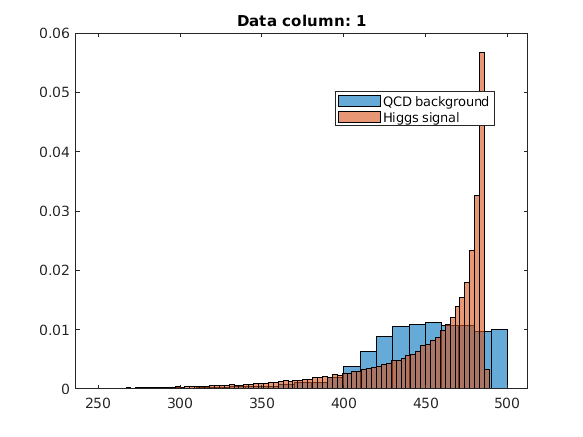

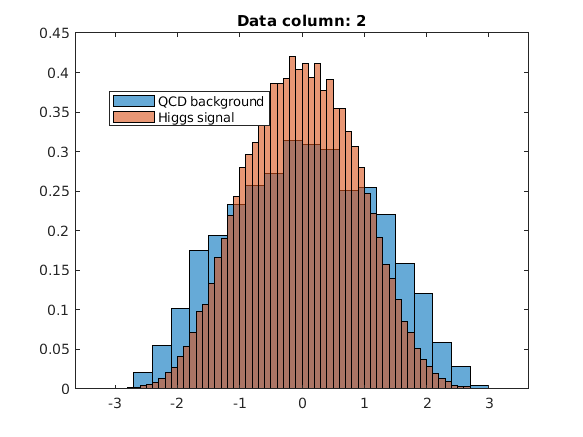

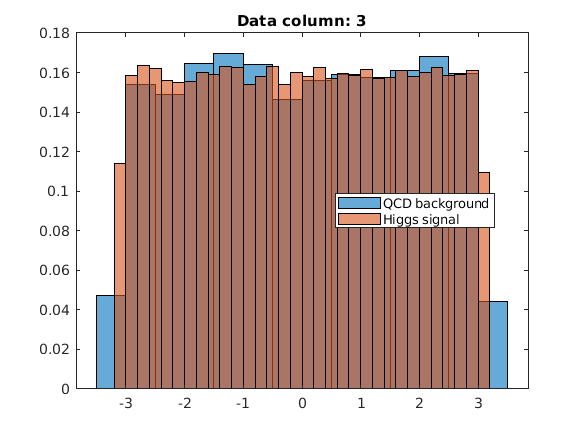

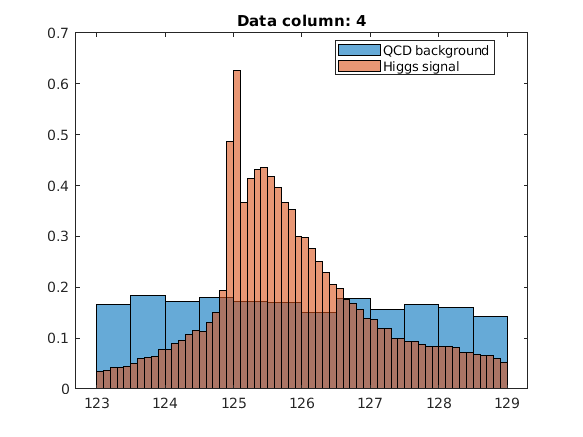

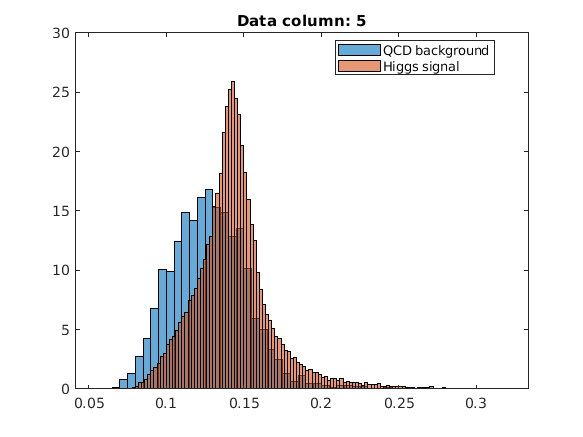

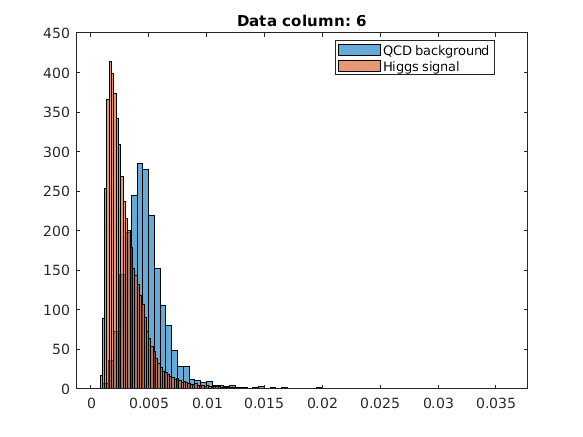

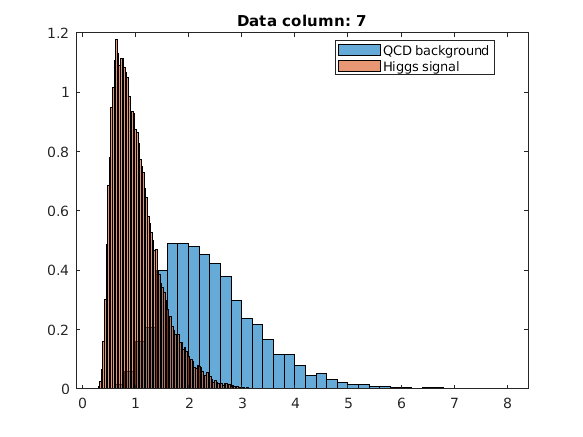

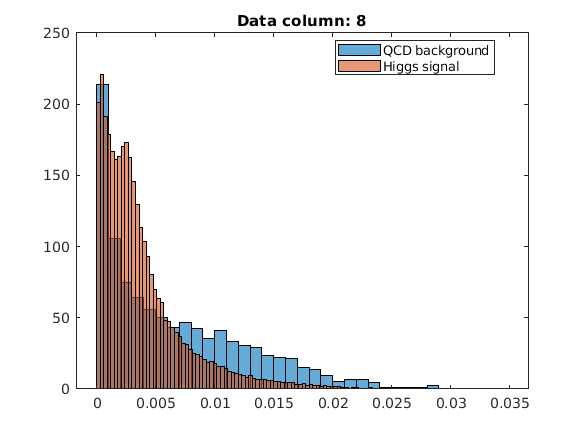

% Keep only data that has mass within mass cut
cutQCD = [];
cutHiggs = [];
for jj = 1:length(dataQCD)
    if dataQCD(jj,4)>123 && dataQCD(jj,4)<129
        % Put row into new matrix
        cutQCD = [cutQCD; dataQCD(jj,:)];
    end
    if dataHiggs(jj,4)>123 && dataHiggs(jj,4)<129
        cutHiggs = [cutHiggs; dataHiggs(jj,:)];
    end
end

% Make plots of each column
for jj=1:14
    figure
    histogram(cutQCD(:,jj),'Normalization','pdf')
    hold on
    histogram(cutHiggs(:,jj),'Normalization','pdf')
    hold off
    title(['Data column: ',num2str(jj)])
    legend('QCD background','Higgs signal','Location','best')
end

It appears that column 7 ($d_2$) provides a reasonable amount of discrimination between background and signal, so we make a cut on this variable next to improve significance.

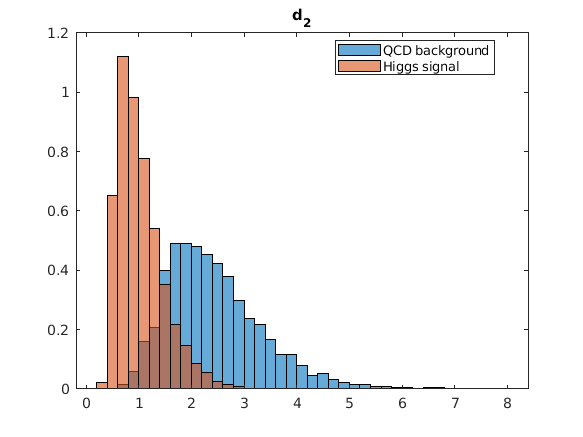

d2QCD = cutQCD(:,7);
d2Higgs = cutHiggs(:,7);
figure
h3QCD = histogram(d2QCD,'Normalization','pdf');
hold on
h3Higgs = histogram(d2Higgs,'Normalization','pdf');
h3Higgs.BinWidth = h3QCD.BinWidth;
hold off
title('d_{2}')
legend('QCD background','Higgs signal','Location','best')

% Normalize to fraction of expected yields
QCDydata = (h3QCD.Values./sum(h3QCD.Values)).*(20000*(length(cutQCD)/100000));
Higgsydata = (h3Higgs.Values./sum(h3Higgs.Values)).*(100*(length(cutHiggs)/100000));
tester = sum(Higgsydata)/sqrt(sum(QCDydata))

tester = 2.8827

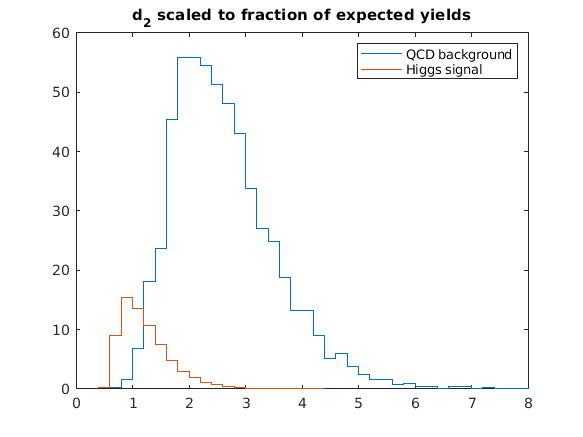

figure
% QCD
stairs(h3QCD.BinEdges(2:end),QCDydata);
hold on
% Higgs
stairs(h3Higgs.BinEdges(2:end),Higgsydata);
title('d_{2} scaled to fraction of expected yields')
legend('QCD background','Higgs signal')
hold off

% start values range from 0.6 to 4.2
qcdStart = 1:13;
higgsStart = 2:14;
% end values range from 0.9 to 4.5
qcdFinish = 2:14;
higgsFinish = 3:15;


ratio3 = zeros(length(qcdStart),length(qcdFinish));
for ii = 1:length(qcdStart)
    for jj = 1:length(qcdFinish)
        % Sum areas of QCD and Higgs histogram in range
        % use ratio to compute significance
        qcdCounts = sum(QCDydata(qcdStart(ii):qcdFinish(jj)));
        higgsCounts = sum(Higgsydata(higgsStart(ii):higgsFinish(jj)));
        ratio3(ii,jj) = higgsCounts./sqrt(qcdCounts);
    end
end

t3 = array2table(ratio3);
rownames = arrayfun(@num2str,h3QCD.BinEdges(1:13),'uni',0);
colnames = arrayfun(@num2str,h3QCD.BinEdges(3:15),'uni',0);
t3.Properties.RowNames = rownames;
t3.Properties.VariableNames = colnames;
disp(t3)

            0.8        1        1.2       1.4        1.6        1.8         2         2.2        2.4        2.6         2.8          3          3.2   
           ______    ______    ______    ______    _______    _______    _______    _______    _______    ________    ________    ________    ________

    0.4    18.149    12.907    9.3783     7.886     6.2134     5.1814     4.5688     4.1377     3.8255      3.5799      3.3948      3.2659      3.1718
    0.6    12.175    9.9721    7.6783    6.6386     5.3046     4.4576 

Choosing a cut that yields the highest significance would lead us to choose 0.6 to 0.8, but this is a very narrow cut to what is already a narrow range. Instead, we choose the cut from 0.6 to 1.6, as that still yields an improved significance of over 5$\sigma$ and gives us more data to work with.

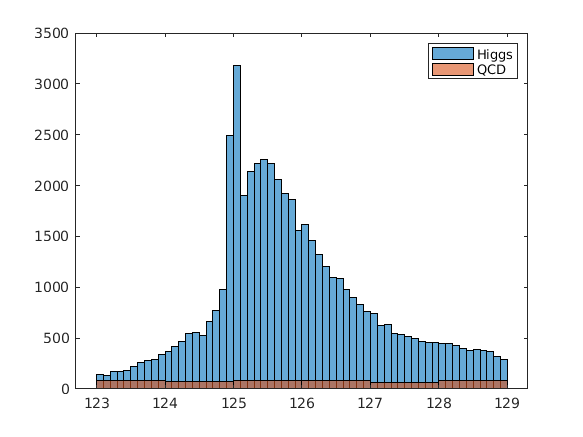

% Make final cut
cut2QCD = [];
cut2Higgs = [];
for jj = 1:length(cutQCD)
    if cutQCD(jj,7)>0.6 && cutQCD(jj,7)<1.6
        % Put row into new matrix
        cut2QCD = [cut2QCD; cutQCD(jj,:)];
    end
end
for jj = 1:length(cutHiggs)
    if cutHiggs(jj,7)>0.6 && cutHiggs(jj,7)<1.6
        cut2Higgs = [cut2Higgs; cutHiggs(jj,:)];
    end
end

figure
histogram(cut2Higgs(:,4))
hold on
histogram(cut2QCD(:,4))
hold off
legend('Higgs','QCD')

We next plot the 2 features with the highest signficance against each other and obtain the scatter plot below.

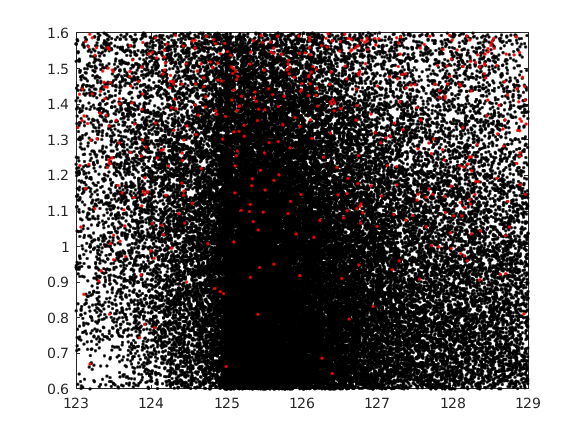

figure
plot(cut2Higgs(:,4),cut2Higgs(:,7),'.','Color','k')
hold on
plot(cut2QCD(:,4),cut2QCD(:,7),'.','Color','r')
hold off

The QCD data (red) concentrated more in the upper portion while the Higgs data (black) is concentrated in the lower middle portion.

## Lab 8

We now want to analyze a pseudo-experiment dataset using cuts optimized on the simulated data. We first examine high luminosity data - data that has more data points to allow us to observe rare processes.

High-Luminosity data

h5disp('data_highLumi_pt_250_500.h5')

HDF5 data_highLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes

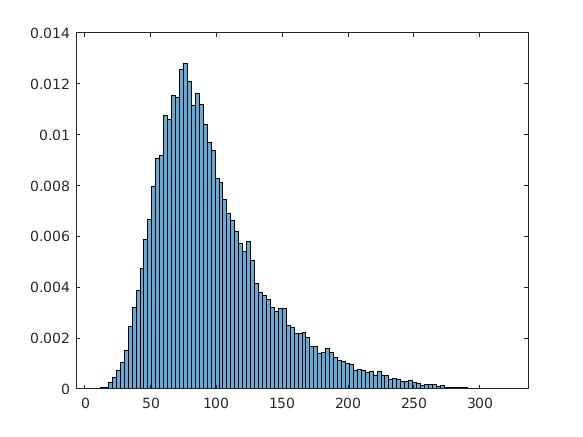

vars = h5read('data_highLumi_pt_250_500.h5','/data/block0_items');
dataHL = h5read('data_highLumi_pt_250_500.h5','/data/block0_values');
figure
hmassHL = histogram(dataHL(4,:),'Normalization','pdf');
hmassHL.BinWidth = 3;

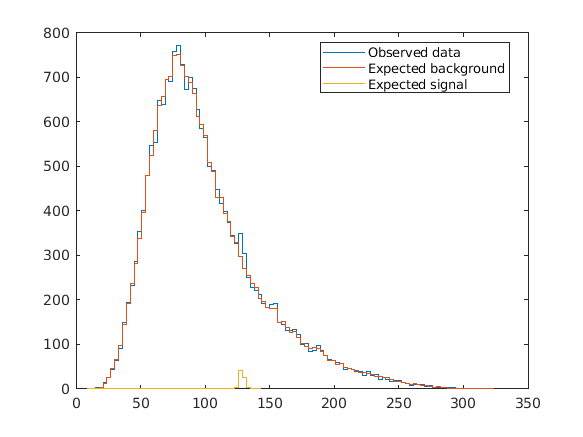

figure
% Observed data
stairs(hmassHL.BinEdges(2:end),(hmassHL.Values./sum(hmassHL.Values))*20100)
hold on
% QCD
stairs(h1.BinEdges(2:end),(h1.Values./sum(h1.Values))*20000)
% Higgs
stairs(h2.BinEdges(2:end),(h2.Values./sum(h2.Values))*100)
legend('Observed data','Expected background','Expected signal','Location','best')
hold off

The plot above superimposes the observed data with the expected background and signal without event selection. The observed data has been rescaled such that the area under the plot is 20,100 since we expected it to contain 20,000 background counts and 100 signal counts.

We next want to see what the plot looks like with optimal event selection established using simulated data, which in this case is a mass cut 123 < m < 129 followed by a cut on $d_2$ from 0.6 to 1.6.

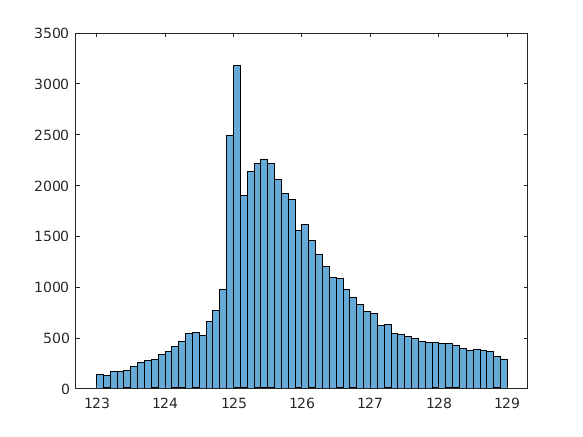

% Mass cut of observed data
% Transpose, each variable is a column
dataHL = dataHL';
cutHL = [];
for jj = 1:length(dataHL)
    if dataHL(jj,4)>123 && dataHL(jj,4)<129
        % Put row into new matrix
        cutHL = [cutHL; dataHL(jj,:)];
    end
end

% d2 cut of observed data
cut2HL = [];
for jj = 1:length(cutHL)
    if cutHL(jj,7)>0.6 && cutHL(jj,7)<1.6
        % Put row into new matrix
        cut2HL = [cut2HL; cutHL(jj,:)];
    end
end

% Plot of data after event selection
figure
h4Higgs = histogram(cut2Higgs(:,4));
hold on
h4QCD = histogram(cut2QCD(:,4));
h4HL = histogram(cut2HL(:,4));
h4QCD.BinWidth = h4Higgs.BinWidth;
h4HL.BinWidth = h4Higgs.BinWidth;
hold off

QCDydata = (h4QCD.Values./sum(h4QCD.Values)).*(20000*(length(cut2QCD)/100000));
Higgsydata = (h4Higgs.Values./sum(h4Higgs.Values)).*(100*(length(cut2Higgs)/100000));
tester2 = sum(Higgsydata)/sqrt(sum(QCDydata))

tester2 = 5.3046

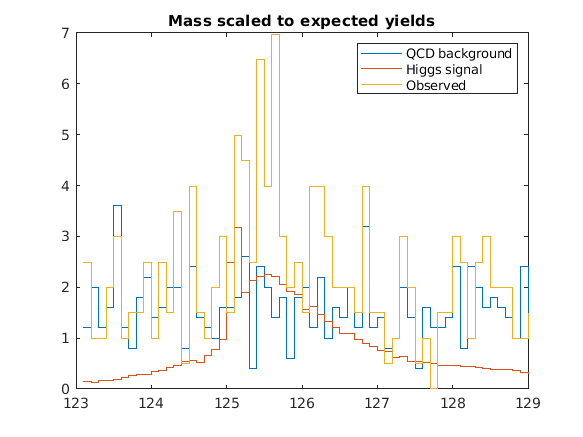

HLydata = (h4HL.Values./sum(h4HL.Values)).*(20100*(length(cut2HL)/40344));
figure
% QCD
stairs(h4QCD.BinEdges(2:end),QCDydata);
hold on
% Higgs
stairs(h4Higgs.BinEdges(2:end),Higgsydata);
% Observed data
stairs(h4HL.BinEdges(2:end),HLydata);
title('Mass scaled to expected yields')
legend('QCD background','Higgs signal','Observed')
hold off

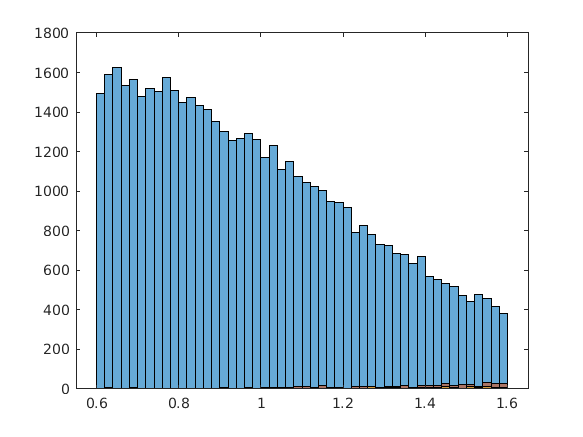

% Plot of data after event selection
figure
h4Higgs = histogram(cut2Higgs(:,7));
hold on
h4QCD = histogram(cut2QCD(:,7));
h4HL = histogram(cut2HL(:,7));
h4QCD.BinWidth = h4Higgs.BinWidth;
h4HL.BinWidth = h4Higgs.BinWidth;
hold off

QCDydata1 = (h4QCD.Values./sum(h4QCD.Values)).*(20000*(length(cut2QCD)/100000));
Higgsydata1 = (h4Higgs.Values./sum(h4Higgs.Values)).*(100*(length(cut2Higgs)/100000));
tester2 = sum(Higgsydata1)/sqrt(sum(QCDydata1))

tester2 = 5.3046

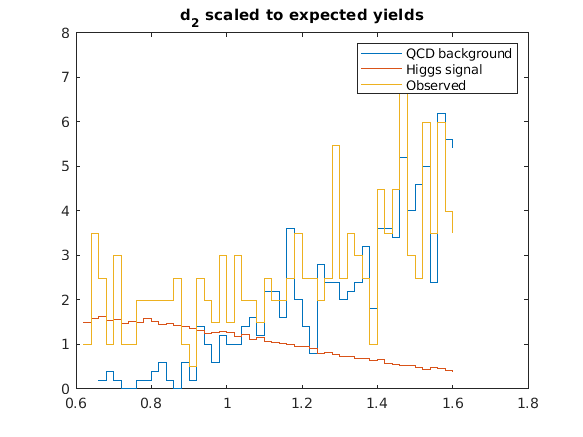

HLydata1 = (h4HL.Values./sum(h4HL.Values)).*(20100*(length(cut2HL)/40344));
figure
% QCD
stairs(h4QCD.BinEdges(2:end),QCDydata1);
hold on
% Higgs
stairs(h4Higgs.BinEdges(2:end),Higgsydata1);
% Observed data
stairs(h4HL.BinEdges(2:end),HLydata1);
title('d_{2} scaled to expected yields')
legend('QCD background','Higgs signal','Observed')
hold off

Evaluate observed significance

In order to evaluate this, we compute $\frac{N_{\textrm{Higgs}} }{\sqrt{N_{\textrm{QCD}} }}$, where we take $N_{\textrm{QCD}}$ to be the same as in the simulated data, and therefore $N_{\textrm{Higgs}}$ is the number left over.

HLsignal = sum(HLydata)-sum(QCDydata);
HLsignificance = HLsignal/sqrt(sum(QCDydata))

HLsignificance = 3.9294

The significance of high-luminosity data is 3.9294$\sigma$, in contrast to the expected significance of 5.3046$\sigma$.

Low-Luminosity data

This section examines a low-luminosity pseudo-experiment.

h5disp('data_lowLumi_pt_250_500.h5')

HDF5 data_lowLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes:

vars = h5read('data_lowLumi_pt_250_500.h5','/data/block0_items');
dataLL = h5read('data_lowLumi_pt_250_500.h5','/data/block0_values');

We plot the mass column of low-luminosity data to get an idea of what it looks like.

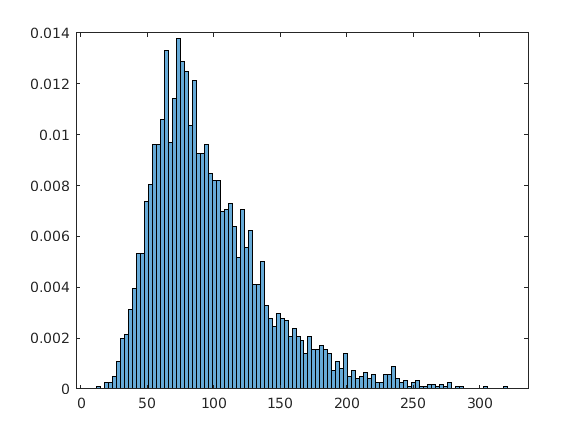

figure
hmassLL = histogram(dataLL(4,:),'Normalization','pdf');
hmassLL.BinWidth = 3;

We also superimpose this data on the simulated data below to see how they look relative to each other.

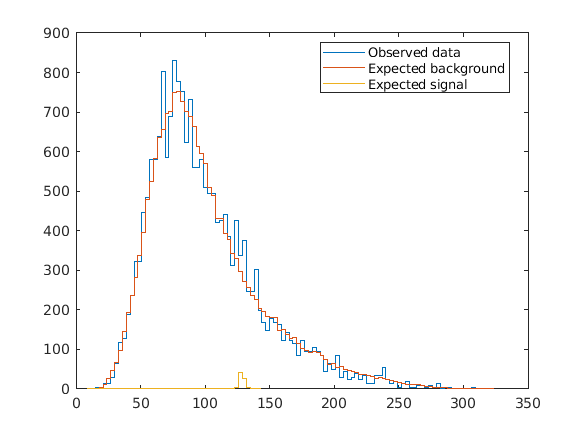

figure
% Observed data
stairs(hmassLL.BinEdges(2:end),(hmassLL.Values./sum(hmassLL.Values))*20100)
hold on
% QCD
stairs(h1.BinEdges(2:end),(h1.Values./sum(h1.Values))*20000)
% Higgs
stairs(h2.BinEdges(2:end),(h2.Values./sum(h2.Values))*100)
legend('Observed data','Expected background','Expected signal','Location','best')
hold off

Next we employ the same data cuts to the low-luminosity data.

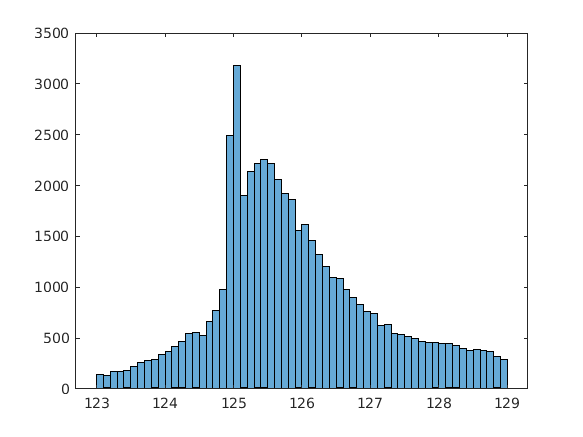

% Mass cut of observed data
% Transpose, each variable is a column
dataLL = dataLL';
cutLL = [];
for jj = 1:length(dataLL)
    if dataLL(jj,4)>123 && dataLL(jj,4)<129
        % Put row into new matrix
        cutLL = [cutLL; dataLL(jj,:)];
    end
end

% d2 cut of observed data
cut2LL = [];
for jj = 1:length(cutLL)
    if cutLL(jj,7)>0.6 && cutLL(jj,7)<1.6
        % Put row into new matrix
        cut2LL = [cut2LL; cutLL(jj,:)];
    end
end

% Plot of data after event selection
figure
h4Higgs = histogram(cut2Higgs(:,4));
hold on
h4QCD = histogram(cut2QCD(:,4));
h4LL = histogram(cut2LL(:,4));
h4QCD.BinWidth = h4Higgs.BinWidth;
h4LL.BinWidth = h4Higgs.BinWidth;
hold off

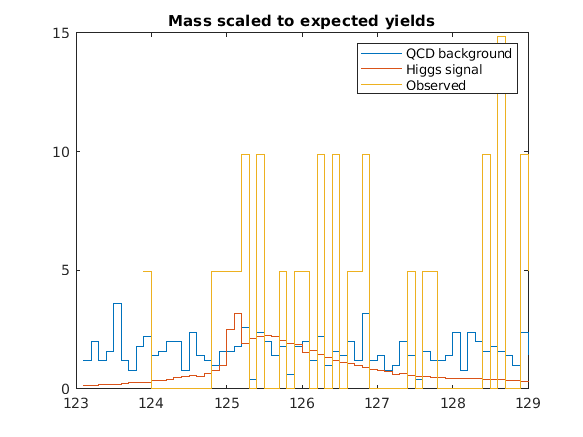

LLydata = (h4LL.Values./sum(h4LL.Values)).*(20100*(length(cut2LL)/4060));
figure
% QCD
stairs(h4QCD.BinEdges(2:end),QCDydata);
hold on
% Higgs
stairs(h4Higgs.BinEdges(2:end),Higgsydata);
% Observed data
stairs(h4LL.BinEdges(2:end),LLydata);
title('Mass scaled to expected yields')
legend('QCD background','Higgs signal','Observed')
hold off

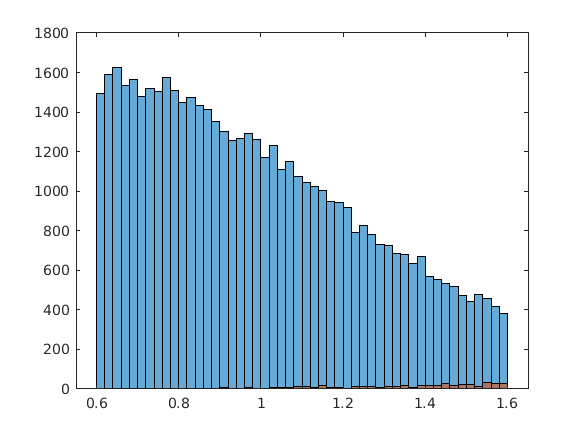

% Plot of data after event selection
figure
h4Higgs = histogram(cut2Higgs(:,7));
hold on
h4QCD = histogram(cut2QCD(:,7));
h4LL = histogram(cut2LL(:,7));
h4QCD.BinWidth = h4Higgs.BinWidth;
h4LL.BinWidth = h4Higgs.BinWidth;
hold off

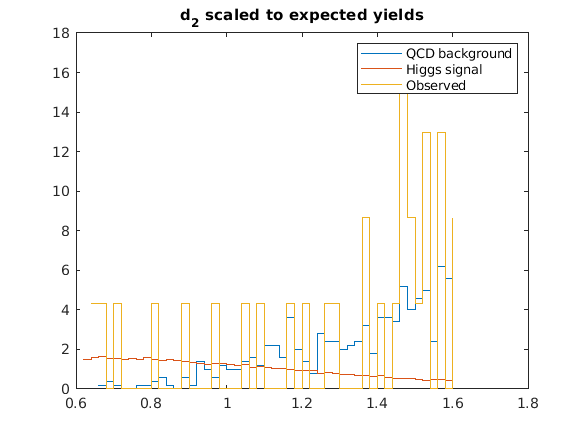


QCDydata1 = (h4QCD.Values./sum(h4QCD.Values)).*(20000*(length(cut2QCD)/100000));
Higgsydata1 = (h4Higgs.Values./sum(h4Higgs.Values)).*(100*(length(cut2Higgs)/100000));
LLydata1 = (h4LL.Values./sum(h4LL.Values)).*(20100*(length(cut2HL)/40344));
figure
% QCD
stairs(h4QCD.BinEdges(2:end),QCDydata1);
hold on
% Higgs
stairs(h4Higgs.BinEdges(2:end),Higgsydata1);
% Observed data
stairs(h4LL.BinEdges(2:end),LLydata1);
title('d_{2} scaled to expected yields')
legend('QCD background','Higgs signal','Observed')
hold off

Evaluate observed significance

We again compute this using $\frac{N_{\textrm{Higgs}} }{\sqrt{N_{\textrm{QCD}} }}$, where we take $N_{\textrm{QCD}}$ to be the same as in the simulated data, and therefore $N_{\textrm{Higgs}}$ is the number left over.

LLsignal = sum(LLydata)-sum(QCDydata);
LLsignificance = LLsignal/sqrt(sum(QCDydata))

LLsignificance = 5.9190

The significance of high-luminosity data is 5.9190$\sigma$, higher than the expected significance of 5.3046$\sigma$.

Evaluate 95% confidence level upper limit

We evauate this for the low-luminosity experiment. The statistical question to be asked is: if I have a candidate signal (a certain number of Higgs counts), then the true value of the signal (number of counts) would be less than *X *95% of the time. We calculate this first for the expected upper limit and then the observed upper limit.

**Expected**

Based on the sum of Higgs counts in the cut range rescaled to expected yields, this number is 51.8660. We multiply this by 0.95 to find the value of *X*.

x1 = 0.95*51.8660

x1 = 49.2727

Based on simulated data, we expect to get 49.2727 counts or less 95% of the time.

**Observed**

We repeat the same calculation for the observed data, which has a signal count of 57.8729.

x2 = 0.95*LLsignal

x2 = 54.9793

We expect to get 54.9793 counts or less 95% of the time in the observed experiment. This is higher than the expected number.